Forecast monthly runoff with ARIMA

## 1 Clear workspace

clear
close all
clc

## 2 Read monthly runoff

data_path='../time_series/';
station='Huaxian' %'Huaxian', 'Xianyang' or 'Zhangjiashan'

station = 'Huaxian'

switch station
    case 'Huaxian'
        save_path = '../Huaxian_modwt/data/';
        data = xlsread([data_path,'HuaxianRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
    
    case 'Xianyang'
        save_path = '../Xianyang_modwt/data/';
        data = xlsread([data_path,'XianyangRunoff1951-2018(1953-2018).xlsx'],1,'B26:B817');%full=792samples
        
    case 'Zhangjiashan'
        save_path = '../Zhangjiashan_modwt/data/';
        data = xlsread([data_path,'ZhangJiaShanRunoff1953-2018(1953-2018).xlsx'],1,'B2:B793');%full=792samples
end

## 3 Tune ARIMA models

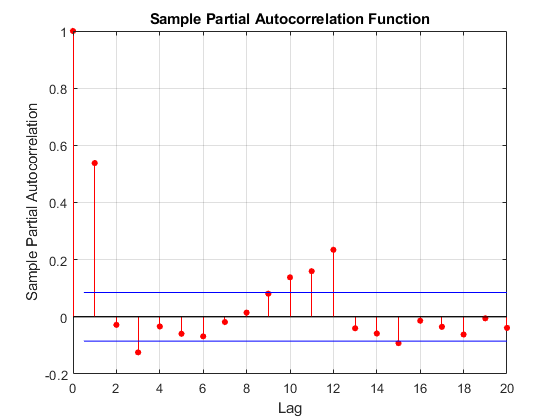

train = data(1:552);
dev = data(553:672);
test = data(673:792);

parcorr(train)

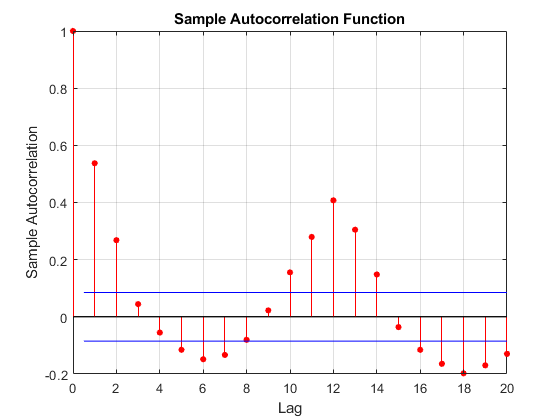

autocorr(train)


m = armax(train,[12,18])


m =
Discrete-time ARMA model: A(z)y(t) = C(z)e(t)                                                                    
                                                                                                                 
  A(z) = 1 - 0.6047 z^-1 + 0.2849 z^-2 + 0.2673 z^-3 - 0.3063 z^-4 + 0.07013 z^-5 - 0.00941 z^-6 - 0.09307 z^-7  
                                     + 0.3485 z^-8 - 0.2062 z^-9 - 0.3959 z^-10 + 0.5485 z^-11 - 0.8872 z^-12    
                                                                                                                 
                                                                                                                 
  C(z) = 1 - 0.1482 z^-1 + 0.2556 z^-2 + 0.3337 z^-3 - 0.08283 z^-4 + 0.05847 z^-5 + 0.02319 z^-6 - 0.05453 z^-7 
          + 0.3587 z^-8 - 0.0309 z^-9 - 0.4253 z^-10 + 0.4339 z^-11 - 0.5569 z^-12 - 0.2509 z^-13 - 0.1122 z^-14 
                                             - 0.02528 z^-15 + 0.004029 z^-16 - 0.0

yp = predict(m,dev,1)

yp =     0.0793
    0.0611
    0.6945
    1.6628
    4.4216
    1.1748
    7.6645
    8.7462
    2.5826
    7.7351


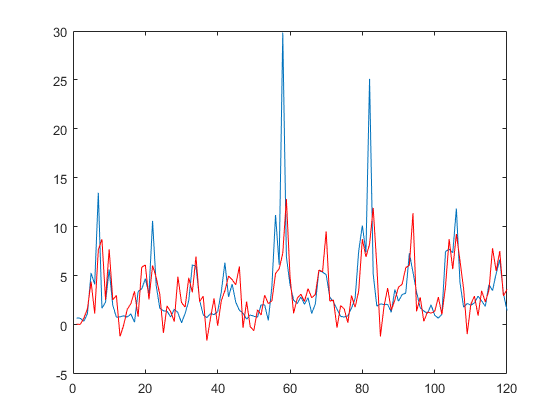


figure
plot(dev);
hold on
plot(yp,'r');
hold off